# Datos Generales

mp = 120                % Masa persona kg

mp = 120

ms = 20                 % Masa silla kg

ms = 20

pp = mp * 9.81          % Peso persona N sugerencia

pp = 1.1772e+03

ps = ms * 9.81          % Peso silla N

ps = 196.2000

mt = mp + ms            % Masa total kg

mt = 140

pt = pp + ps            % Peso total N

pt = 1.3734e+03

# Datos Perfiles

lbc = 430               % Longitud barra corta mm

lbc = 430

lbl = 2360              % Longitud barra larga mm

lbl = 2360

lbm = 355               % longitud barra motor mm

lbm = 355

pbc = 3.08 / 1000       % Masa teórico calculado barra corta kg/mm

pbc = 0.0031

pbl = 6.39 / 1000       % Masa teórico calculado barra larga kg/mm 

pbl = 0.0064

#### ***Areas***

- ***Perfil 1 - 50 x 50 ***

b11 = 50            % mm

b11 = 50

h11 = 50            % mm

h11 = 50

A11 = b11 * h11     % mm^2

A11 = 2500


b12 = 46            % mm

b12 = 46

h12 = 46            % mm

h12 = 46

A12 = b12 * h12     % mm^2

A12 = 2116


A1 = A11 - A12      % mm^2

A1 = 384

- ***Perfil 2 - 70 x 70***

b21 = 70            % mm

b21 = 70

h21 = 70            % mm

h21 = 70

A21 = b21 * h21     % mm^2

A21 = 4900


b22 = 67            % mm

b22 = 67

h22 = 67            % mm

h22 = 67

A22 = b22 * h22     % mm^2

A22 = 4489


A2 = A21 - A22      % mm^2

A2 = 411

#### ***Momentos de Inercia***

- *** Perfil 1 - 50 x 50***

I1 = ((b11 * h11^3) / 12) - ((b12 * h12^3) / 12)    % mm^4

I1 = 147712

c1 = h11 / 2                                        % mm

c1 = 25

- *** Perfil 1 - 70 x 70***

I2 = ((b21 * h21^3) / 12) - ((b22 * h22^3) / 12)    % mm^4

I2 = 3.2157e+05

c2 = h21 / 2                                        % mm

c2 = 35

# Movimiento del Marco

alpha = 6      %Grados Balanceo

alpha = 6

betha = 17      %Grados Cabeceo

betha = 17

# Peso de las vigas

- ***Viga 430 mm - Perfil 1***

m1 = pbc*lbc*9.81       %N

m1 = 12.9924

- ***Viga 355 mm - Perfil 1***

m2 = pbc*lbm*9.81       %N

m2 = 10.7263

- ***Viga 2360 mm -Perfil 2***

m3 = pbl*lbl*9.81       %N

m3 = 147.9387

# Fuerzas

- ***Fuerza Total (Peso Viga + Fuerza Externa)***

W1 = pt + m1        %Vigas 430mm (N)

W1 = 1.3864e+03

W2 = m2             %Vigas 355mm (N)

W2 = 10.7263

W3 = m3             %Vigas 2360mm (N)

W3 = 147.9387

- ***Fuerza Fa***

Fa = 10000      %N

Fa = 10000

- ***Fuerza Fm***

Fm = 10000      %N

Fm = 10000

## ***Componentes de las Fuerzas***

Cx = cosd(alpha).*sind(betha);
Cy = sind(alpha);
Cz = cosd(alpha).*cosd(betha);


- ***W1***

W1x = W1.*Cx

W1x = 403.1214

W1y = W1.*Cy

W1y = 144.9175

W1z = W1.*Cz

W1z = 1.3186e+03

- ***W2***

W2x = W2.*Cx

W2x = 3.1189

W2y = W2.*Cy

W2y = 1.1212

W2z = W2.*Cz

W2z = 10.2014

- ***W3***

W3x = W3.*Cx

W3x = 43.0162

W3y = W3.*Cy

W3y = 15.4638

W3z = W3.*Cz

W3z = 140.6995

- ***Fa***

Fax = Fa.*Cx

Fax = 2.9077e+03

Fay = Fa.*Cy

Fay = 1.0453e+03

Faz = Fa.*Cz

Faz = 9.5107e+03

- ***Fm***

Fmx = -Fm.*Cx

Fmx = -2.9077e+03

Fmy = -Fm.*Cy

Fmy = -1.0453e+03

Fmz = -Fm.*Cz

Fmz = -9.5107e+03

# Análisis de Vigas

## 1. Viga 1

a = lbc/2;        %Distancia de aplicacion de la Carga
X1 = 0:0.05:lbc;

### Plano XZ

[R1z,M1y,R2z,M2y,R1x,R2x] = Doble_Simple(W1z,a,lbc,-W1x)

R1z = 659.2753

M1y = 7.0872e+04

R2z = 659.2753

M2y = 7.0872e+04

R1x = -201.5607

R2x = -201.5607

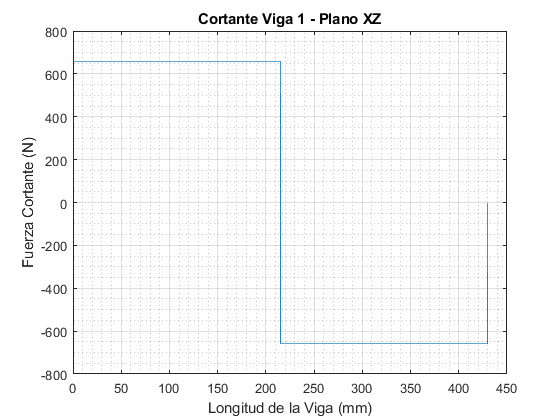


V1xz = R1z - W1z.*ctstep(X1-a)+R2z.*(X1==lbc);
plot(X1,V1xz)
grid on
grid minor
title('Cortante Viga 1 - Plano XZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V1max_xz = max(V1xz)            %(N)

V1max_xz = 659.2753

V1min_xz = min(V1xz)            %(N)

V1min_xz = -659.2753

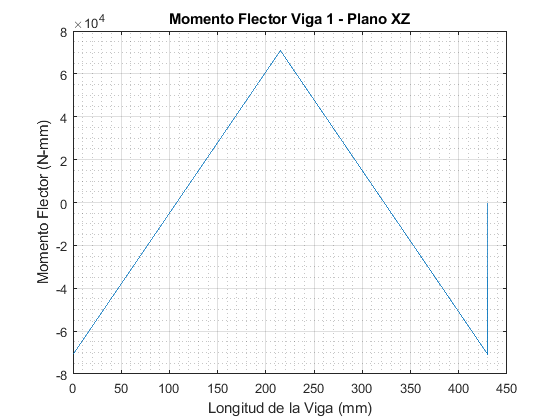


M1xz = -M1y + R1z.*(X1)-W1z.*ctstep(X1-a).*(X1-a)+M2y.*(X1==lbc);
plot(X1,M1xz)
grid on
grid minor
title('Momento Flector Viga 1 - Plano XZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M1max_xz = max(M1xz)            %(N-mm)

M1max_xz = 7.0872e+04

M1min_xz = min(M1xz)            %(N-mm)

M1min_xz = -7.0872e+04

### Plano XY

[R1y,M1z,R2y,M2z,R1x,R2x] = Doble_Simple(W1y,a,lbc,-W1x)

R1y = 72.4587

M1z = 7.7893e+03

R2y = 72.4587

M2z = 7.7893e+03

R1x = -201.5607

R2x = -201.5607

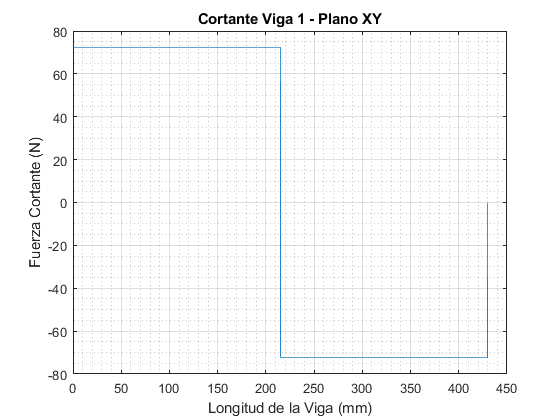


V1xy = R1y - W1y.*ctstep(X1-a)+R2y.*(X1==lbc);
plot(X1,V1xy)
grid on
grid minor
title('Cortante Viga 1 - Plano XY')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V1max_xy = max(V1xy)            %(N)

V1max_xy = 72.4587

V1min_xy = min(V1xy)            %(N)

V1min_xy = -72.4587

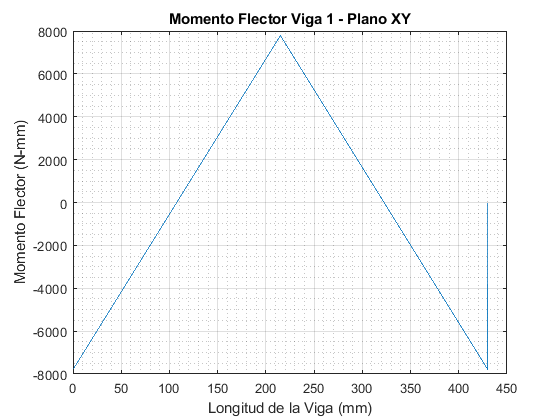


M1xy = -M1z + R1y.*(X1)-W1y.*ctstep(X1-a).*(X1-a)+M2z.*(X1==lbc);
plot(X1,M1xy)
grid on
grid minor
title('Momento Flector Viga 1 - Plano XY')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M1max_xy = max(M1xy)            %(N-mm)

M1max_xy = 7.7893e+03

M1min_xy = min(M1xy)            %(N-mm)

M1min_xy = -7.7893e+03

## 2. Viga 2

a = lbc/2;          %Distancia de aplicacion de la Carga
X1 = 0:0.05:lbc;

### Plano XZ

[R3z,M3y,R4z,M4y,R3x,R4x] = Doble_Simple(W1z,a,lbc,-W1x)

R3z = 659.2753

M3y = 7.0872e+04

R4z = 659.2753

M4y = 7.0872e+04

R3x = -201.5607

R4x = -201.5607

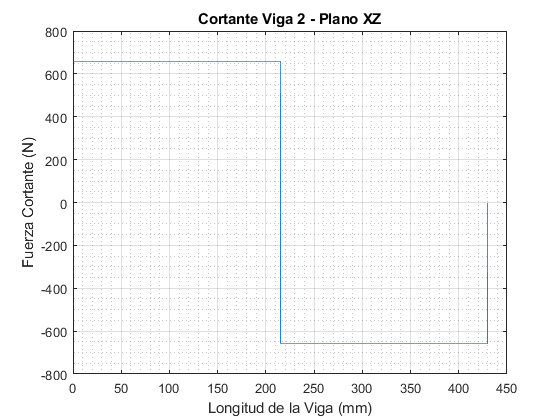


V2xz = R3z - W1z.*ctstep(X1-a)+R4z.*(X1==lbc);
plot(X1,V2xz)
grid on
grid minor
title('Cortante Viga 2 - Plano XZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V2max_xz = max(V2xz)            %(N)

V2max_xz = 659.2753

V2min_xz = min(V2xz)            %(N)

V2min_xz = -659.2753

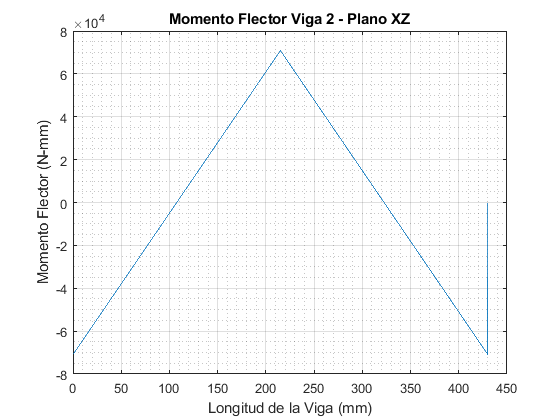


M2xz = -M3y + R3z.*(X1)-W1z.*ctstep(X1-a).*(X1-a)+M4y.*(X1==lbc);
plot(X1,M2xz)
grid on
grid minor
title('Momento Flector Viga 2 - Plano XZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M2max_xz = max(M2xz)            %(N-mm)

M2max_xz = 7.0872e+04

M2min_xz = min(M2xz)            %(N-mm)

M2min_xz = -7.0872e+04

### Plano XY

[R3y,M3z,R4y,M4z,R3x,R4x] = Doble_Simple(W1y,a,lbc,-W1x)

R3y = 72.4587

M3z = 7.7893e+03

R4y = 72.4587

M4z = 7.7893e+03

R3x = -201.5607

R4x = -201.5607

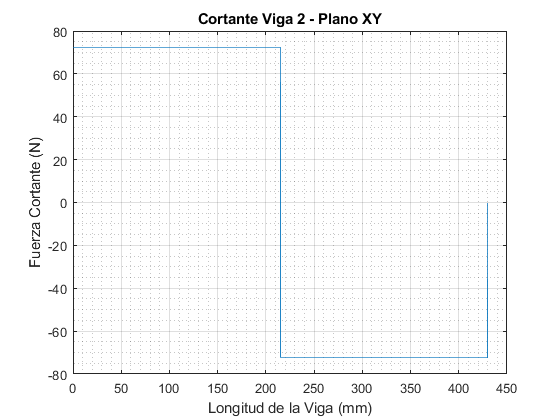


V2xy = R3y - W1y.*ctstep(X1-a)+R4y.*(X1==lbc);
plot(X1,V2xy)
grid on
grid minor
title('Cortante Viga 2 - Plano XY')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V2max_xy = max(V2xy)            %(N)

V2max_xy = 72.4587

V2min_xy = min(V2xy)            %(N)

V2min_xy = -72.4587

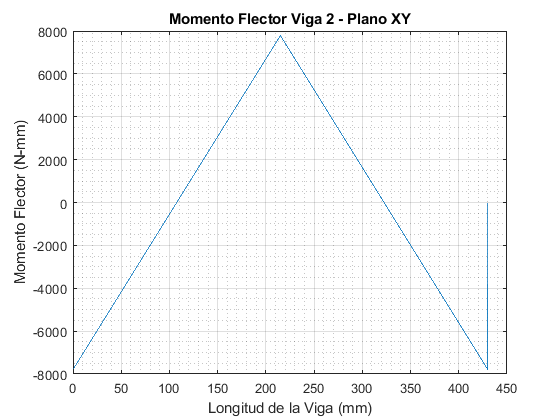


M2xy = -M3z + R3y.*(X1)-W1y.*ctstep(X1-a).*(X1-a)+M4z.*(X1==lbc);
plot(X1,M2xy)
grid on
grid minor
title('Momento Flector Viga 2 - Plano XY')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M2max_xy = max(M2xy)            %(N-mm)

M2max_xy = 7.7893e+03

M2min_xy = min(M2xy)            %(N-mm)

M2min_xy = -7.7893e+03

## 3. Viga 4

a = lbm/3;           %Distancia de aplicacion de la Carga 1
b = lbm/2;           %Distancia de aplicación de la Carga 2
b1 = b-a;
c = lbm-b;

X1 = 0:0.001:lbm;

### Plano XZ

[R9z,M9y,R10z,M10y,R9x,R10x] = Doble_Doble(Fmz,W2z,a,b1,c,Fmx,W2x) 

R9z = -9.1439e+03

M9y = 1.3085e+06

R10z = -356.5150

M10y = 3.1141e+05

R9x = -1.9369e+03

R10x = -967.6741

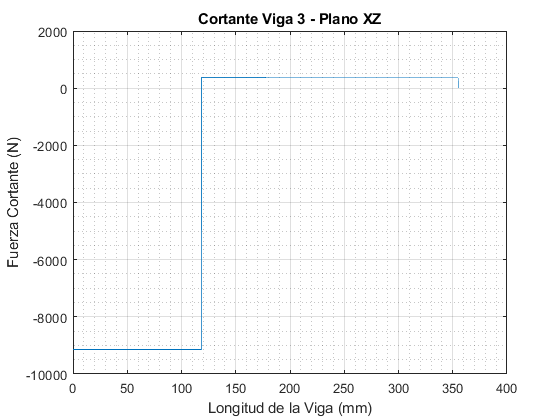


V3xz = R9z-Fmz.*ctstep(X1-a)-W2z.*ctstep(X1-b)+R10z.*(X1==lbm);
plot(X1,V3xz)
grid on
grid minor
title('Cortante Viga 3 - Plano XZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V3max_xz = max(V3xz)            %(N)

V3max_xz = 366.7164

V3min_xz = min(V3xz)            %(N)

V3min_xz = -9.1439e+03

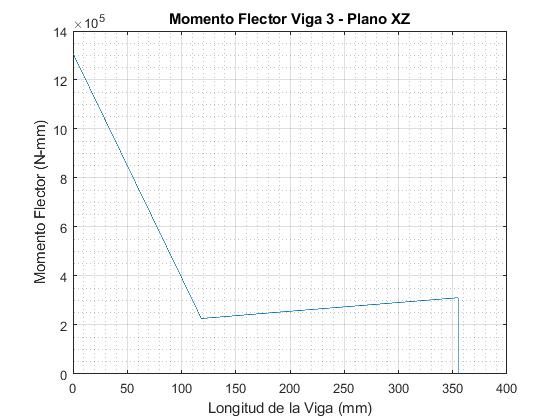


M3xz = M9y+R9z.*X1-Fmz.*ctstep(X1-a).*(X1-a)-W2z.*ctstep(X1-b).*(X1-b)-M10y.*(X1==lbm);
plot(X1,M3xz)
grid on
grid minor
title('Momento Flector Viga 3 - Plano XZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M3max_xz = max(M3xz)            %(N-mm)

M3max_xz = 1.3085e+06

M3min_xz = min(M3xz)            %(N-mm)

M3min_xz = 2.3283e-10

### Plano XY

[R9y,M9z,R10y,M10z,R9x,R10x] = Doble_Doble(Fmy,W2y,a,b1,c,Fmx,W2x) 

R9y = -1.0050e+03

M9z = 1.4381e+05

R10y = -39.1834

M10z = 3.4226e+04

R9x = -1.9369e+03

R10x = -967.6741

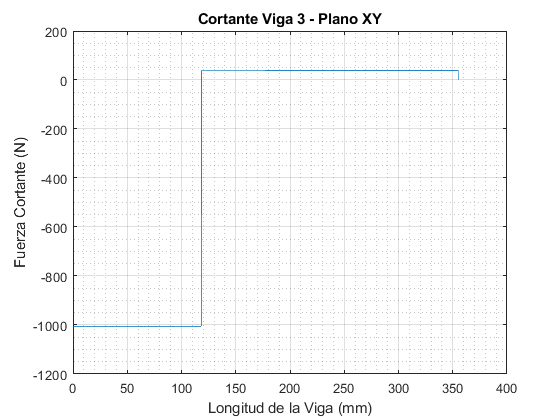


V3xy = R9y-Fmy.*ctstep(X1-a)-W2y.*ctstep(X1-b)+R10y.*(X1==lbm);

plot(X1,V3xy)
grid on
grid minor
title('Cortante Viga 3 - Plano XY')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V3max_xy = max(V3xy)            %(N)

V3max_xy = 40.3046

V3min_xy = min(V3xy)            %(N)

V3min_xy = -1.0050e+03

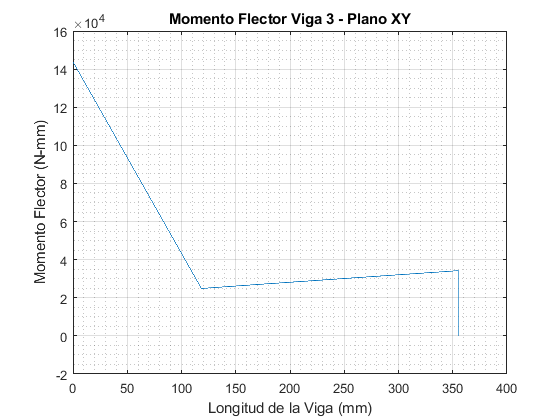


M3xy = M9z+R9y.*X1-Fmy.*ctstep(X1-a).*(X1-a)-W2y.*ctstep(X1-b).*(X1-b)-M10z.*(X1==lbm);
plot(X1,M3xy)
grid on
grid minor
title('Momento Flector Viga 3 - Plano XY')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M3max_xy = max(M3xy)            %(N-mm)

M3max_xy = 1.4381e+05

M3min_xy = min(M3xy)            %(N-mm)

M3min_xy = -4.3656e-11

## 4. Viga 3

a = 90;           %Distancia de aplicacion de la Carga 1
b = lbc/2;           %Distancia de aplicación de la Carga 2
b1 = b-a;
c = lbc-b;

X1 = 0:0.001:lbc;

### Plano XZ

[R5z,M5y,R6z,M6y,R5x,R6x] = Doble_Doble(-abs(R9z),W1z,a,b1,c,-abs(R9y),W1x) 

R5z = -8.1490e+03

M5y = 8.4957e+05

R6z = 323.6155

M6y = 1.7095e+05

R5x = -593.0747

R6x = -8.7840

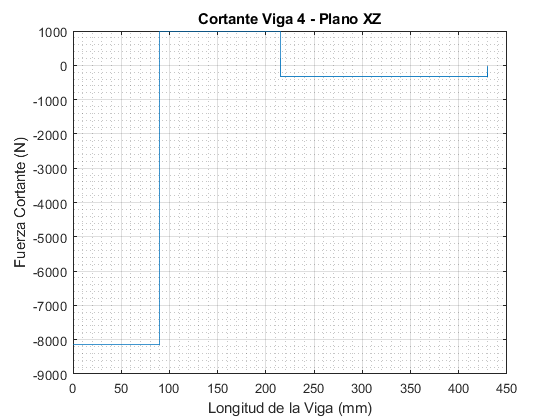


V4xz = R5z-R9z.*ctstep(X1-a)-W1z.*ctstep(X1-b)+R6z.*(X1==lbc);
plot(X1,V4xz)
grid on
grid minor
title('Cortante Viga 4 - Plano XZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V4max_xz = max(V4xz)            %(N)

V4max_xz = 994.9351

V4min_xz = min(V4xz)            %(N)

V4min_xz = -8.1490e+03

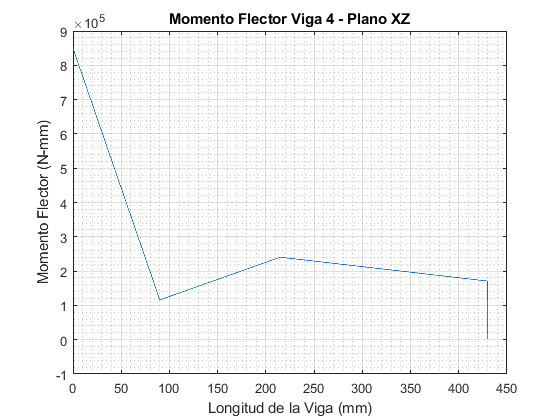


M4xz = M5y+R5z.*X1-R9z.*ctstep(X1-a).*(X1-a)-W1z.*ctstep(X1-b).*(X1-b)-M6y.*(X1==lbc);
plot(X1,M4xz)
grid on
grid minor
title('Momento Flector Viga 4 - Plano XZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M4max_xz = max(M4xz)            %(N-mm)

M4max_xz = 8.4957e+05

M4min_xz = min(M4xz)            %(N-mm)

M4min_xz = -3.4925e-10

### Plano XY

[R5y,M5z,R6y,M6z,R5x,R6x] = Doble_Doble(abs(R9x),W1y,a,b1,c,-abs(R9y),W1x) 

R5y = 2.0178e+03

M5z = -2.0843e+05

R6y = 64.0650

M6z = -3.0501e+04

R5x = -593.0747

R6x = -8.7840

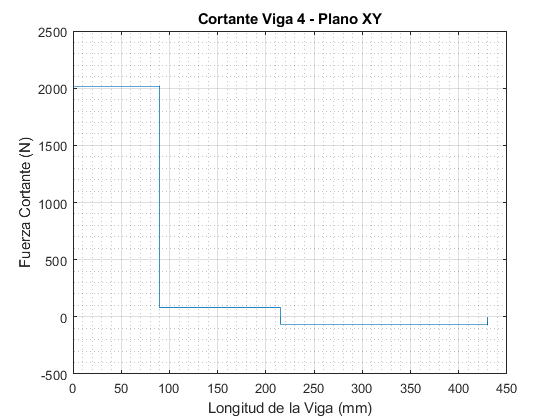


V4xy = R5y+R9x.*ctstep(X1-a)-W1y.*ctstep(X1-b)+R6y.*(X1==lbc);

plot(X1,V4xy)
grid on
grid minor
title('Cortante Viga 4 - Plano XY')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V4max_xy = max(V4xy)            %(N)

V4max_xy = 2.0178e+03

V4min_xy = min(V4xy)            %(N)

V4min_xy = -64.0650

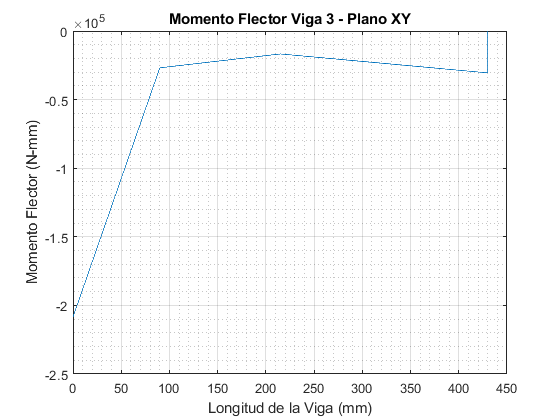


M4xy = M5z+R5y.*X1+R9x.*ctstep(X1-a).*(X1-a)-W1y.*ctstep(X1-b).*(X1-b)-M6z.*(X1==lbc);
plot(X1,M4xy)
grid on
grid minor
title('Momento Flector Viga 3 - Plano XY')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M4max_xy = max(M4xy)            %(N-mm)

M4max_xy = -3.6380e-11

M4min_xy = min(M4xy)            %(N-mm)

M4min_xy = -2.0843e+05

### Torque

[M5x,M6x] = Torque(-abs(M9y),a,b1+c)

M5x = -1.0346e+06

M6x = -2.7386e+05

M9y = -M9y

M9y = -1.3085e+06

## 5. Viga 5

a = 90;           %Distancia de aplicacion de la Carga 1
b1 = lbc/2;          %Distancia de aplicación de la Carga 2
b = b1-a;
c = lbc/2;           %Distancia de aplicación de la carga 3
L = lbc;

X1 = 0:0.001:lbc;

### Plano XZ

[R7z,M7y,R8z,M8y,R7x,R8x] = Doble_Triple(-abs(R10z),W1z,Faz,a,b,c,L,-abs(R10y),W1x,Fax)

R7z = -7.2158e+03

M7y = -7.7726e+05

R8z = -1.3328e+03

M8y = 4.4302e+05

R7x = 1.6244e+03

R8x = 1.6472e+03

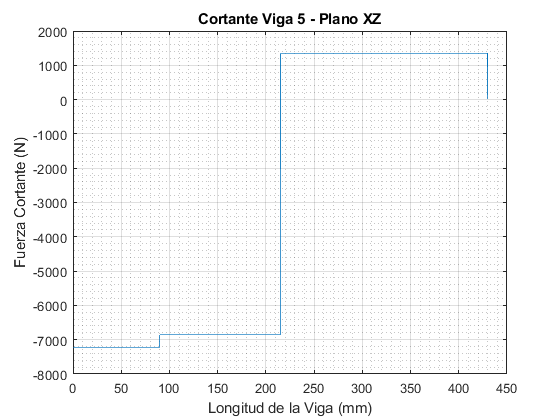


V5xz = R7z+abs(R10z).*ctstep(X1-a)-W1z.*ctstep(X1-b1)+Faz.*ctstep(X1-c)+R8z.*(X1==lbc);
plot(X1,V5xz)
grid on
grid minor
title('Cortante Viga 5 - Plano XZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V5max_xz = max(V5xz)            %(N)

V5max_xz = 1.3328e+03

V5min_xz = min(V5xz)            %(N)

V5min_xz = -7.2158e+03

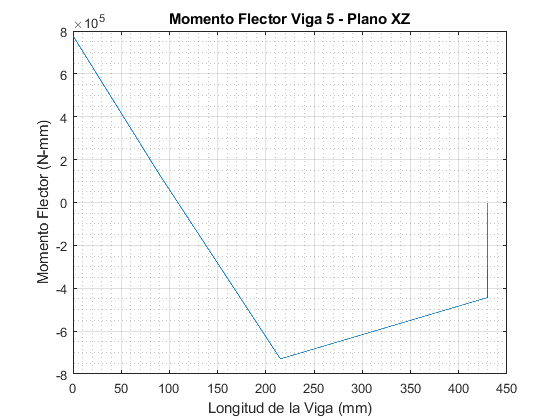


M5xz = -M7y+R7z.*X1+abs(R10z).*ctstep(X1-a).*(X1-a)-W1z.*ctstep(X1-b1).*(X1-b1)+Faz.*ctstep(X1-c).*(X1-c)+M8y.*(X1==lbc);
plot(X1,M5xz)
grid on
grid minor
title('Momento Flector Viga 5 - Plano XZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M5max_xz = max(M5xz)            %(N-mm)

M5max_xz = 7.7726e+05

M5min_xz = min(M5xz)            %(N-mm)

M5min_xz = -7.2957e+05

### Plano XY

[R7y,M7z,R8y,M8z,R7x,R8x] = Doble_Triple(abs(R10x),W1y,Fay,a,b,c,L,-abs(R10y),W1x,Fax) 

R7y = 187.5887

M7z = -1.5547e+04

R8y = -120.2818

M8z = 3.9220e+04

R7x = 1.6244e+03

R8x = 1.6472e+03

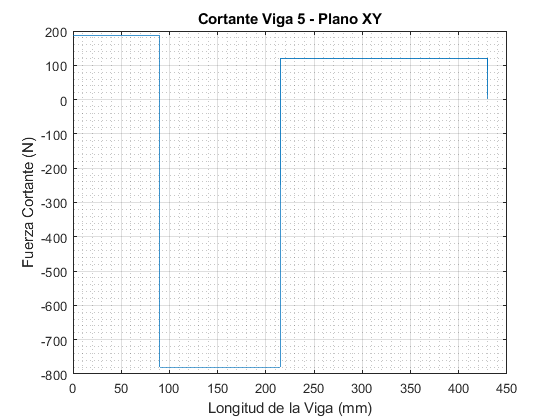


V5xy = R7y-abs(R10x).*ctstep(X1-a)-W1y.*ctstep(X1-b1)+Fay.*ctstep(X1-c)+R8y.*(X1==lbc);

plot(X1,V5xy)
grid on
grid minor
title('Cortante Viga 5 - Plano XY')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V5max_xy = max(V5xy)            %(N)

V5max_xy = 187.5887

V5min_xy = min(V5xy)            %(N)

V5min_xy = -780.0854

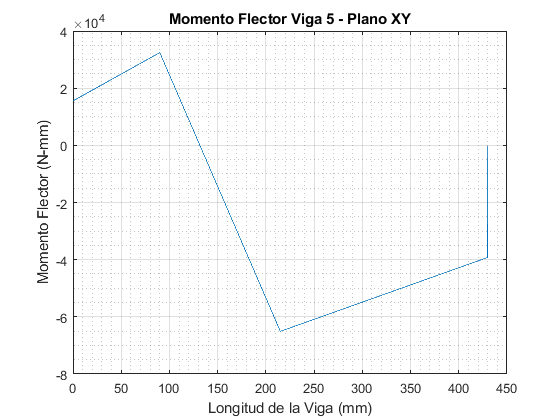


M5xy = -M7z+R7y.*X1-abs(R10x).*ctstep(X1-a).*(X1-a)-W1y.*ctstep(X1-b1).*(X1-b1)+Fay.*ctstep(X1-c).*(X1-c)+M8z.*(X1==lbc);
plot(X1,M5xy)
grid on
grid minor
title('Momento Flector Viga 5 - Plano XY')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M5max_xy = max(M5xy)            %(N-mm)

M5max_xy = 3.2430e+04

M5min_xy = min(M5xy)            %(N-mm)

M5min_xy = -6.5081e+04

### Torque

[M7x,M8x] = Torque(abs(M10y),a,L-a)

M7x = 2.4623e+05

M8x = 6.5179e+04

M10y = -M10y

M10y = -3.1141e+05

## 6. Viga 6

L = lbl/2;                     % mm
a = 355;      %Distancia entre la viga 1 y 2  (mm)
b = 180;      %Distancia entre la viga 2 y 3  (mm)
c = 355;      %Distancia entre la viga 3 y 4  (mm)
d = 585/2;      %Distancia entre la viga 4 y el centro de la viga (mm)
X1 = 0:0.005:L;

### Plano YZ

R11z = -R1z-R3z-R5z-R7z-(W3z/2)

R11z = 1.3976e+04

M11x = M5x+M7x+(R1z).*L+(R3z).*(L-a)+(R5z).*(c+d)+(R7z).*(d)+(W3z/2).*(L/2)

M11x = -6.8121e+06

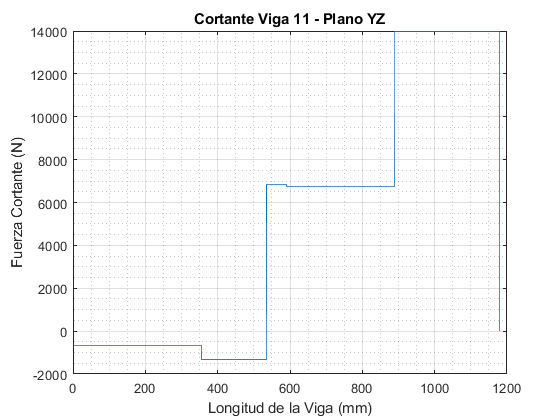


V11yz = -R1z-R3z.*ctstep(X1-a)-R5z.*ctstep(X1-(a+b))-R7z.*ctstep(X1-(a+b+c))-(W3z/2).*ctstep(X1-L/2)-R11z.*(X1==L);

plot(X1,V11yz)
grid on
grid minor
title('Cortante Viga 11 - Plano YZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Fuerza Cortante (N)')


V11max_yz = max(V11yz)            %(N)

V11max_yz = 1.3976e+04

V11min_yz = min(V11yz)            %(N)

V11min_yz = -1.3186e+03

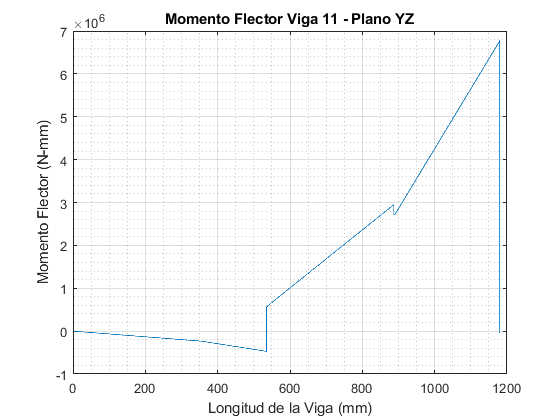


M11yz = -M5x.*ctstep(X1-(a+b))-M7x.*ctstep(X1-(L-d))-R1z.*X1-R3z.*ctstep(X1-a).*(X1-a)-R5z.*ctstep(X1-(a+b)).*(X1-(a+b))-R7z.*ctstep(X1-(a+b+c)).*(X1-(a+b+c))-(W3z/2).*ctstep(X1-L/2).*(X1-L/2)+M11x.*(X1==L);
plot(X1,M11yz)
grid on
grid minor
title('Momento Flector Viga 11 - Plano YZ')
xlabel('Longitud de la Viga (mm)')
ylabel('Momento Flector (N-mm)')


M11max_yz = max(M11yz)            %(N-mm)

M11max_yz = 6.7736e+06

M11min_yz = min(M11yz)            %(N-mm)

M11min_yz = -4.7138e+05

### Plano XY

### Torque

# Viga Doblemente Empotrada: Carga Puntual

function[Ay,Ma,By,Mb,Ax,Bx] = Doble_Simple(P,a,L,F)
b = L-a;
Ay =((P*(b^2))/(L^3)).*(b+(3.*a));
Ma =(P*(b^2)*a)/(L^2);
By =((P*(a^2))/(L^3)).*(a+(3.*b));
Mb =(P*(a^2)*b)/(L^2);

Ax =(F*b)/(a+b);
Bx =(F*a)/(a+b);
end

# Viga Doblemente Empotrada: Doble Carga Puntual

function[Ay,Ma,By,Mb,Ax,Bx] = Doble_Doble(P,N,a,b,c,F,T)
d = a+b;
L = a+b+c;

By = -((3*P*(a^2))-(6*P*a*b)-(6*P*a*c)-(4*P*(a^3))+(3*N*(d^2))-(6*N*c*(d^2))-(4*N*(d^3)))/((L^2)*((4*L)-3));
Mb = ((4*P*(a^3))-(8*L*P*(a^2))+(3*P*(a^2))+(6*P*a*b)+(6*P*a*c)+(4*N*(d^3))-(4*L*N*(d^2))+(6*N*c*(d^2)))/((2*L)*((4*L)-3));
Ay = P+N-By;
Ma = Mb-(P*a)-(N*d)+(By*L);

Bx = (T*(b+a)+(F*a))/(a+b+c);
Ax = F+T-Bx;
end

# Viga Doblemente Empotrada: Triple Carga Puntual

function[Ay,Ma,By,Mb,Ax,Bx] = Doble_Triple(P,N,F,a,b,c,L,K,T,H)
d = a+b;
By = ((3*P*(a^3))-(3*P*L*(a^2))+(2*N*(d^3))-(3*N*L*(d^2))-(2+F*(c^3))+(3*F*L*(c^2)))/((3*(L^2))-(4*(L^3)));
%Mb = (-(P*(a^3))-(2*P*(a^2)*(L^2))+(3*P*L*(a^2))-(2*N*(L^2)*(d^2))-(N*(d^3))+(F*(c^3))+(2*F*(L^2)*(c^2))-(3*F*L*(c^2)))/((L^2)*((4*L)-3));
Mb = (1/(2*L)).*(-(P*(a^2))-(N*(d^2))+(F*(c^2))+(By*L));
Ay = P+N-F-By;
Ma = Mb+(P*a)-(F*c)+(N*d)-(By*L);

Bx = ((a*(K+T+H))+(b*(T+H))+(H*(abs((L-(a+b))-(L-c)))))/L;
Ax = K+T+H-Bx;
end

# Torque

function [M1,M2] = Torque(T,a,b)
M2 = T/((b/a)+1);
M1 = (T*b)/(a+b);
end

# Escalón Unitario

function [u] = ctstep(t)
u = (t>=0).*(1) + (t<0).*(0);
end